clc, clear, close all

Input:

h = 10000 %Desired altitude

h = 10000

Calculations:

g = 9.81; %m/s^2  
To = 288.15; %Kelvin
po = 101325; %Pa
R = 287.04; %Air constant
p11 = 22632; %Pa Above tropopause
T11 = 216.65; %K Above tropopause
h11 = 11000; %meters
a0 = 340.294; %m/s

%Solves air conditions for a specific height
if h<11001 %Under tropopause
    T = To-6.5*(h/1000);
    p = po*(1-0.0065*(h/To))^5.2561;
else %Above tropopause
    T = 216.65;
    p = p11*exp(-g/(R*T11)*(h-h11));
end
rho = p/(R*T);
a = sqrt(1.41*p/rho);
X = ['Pressure: ', num2str(p), ' Pa',...
     ' Density: ', num2str(rho), ' kg/m3',...
    ' Temperature: ', num2str(T-273), ' ºC'];
disp(X)

Pressure: 26434.7546 Pa Density: 0.4127 kg/m3 Temperature: -49.85 ºC


Graphic Representations:

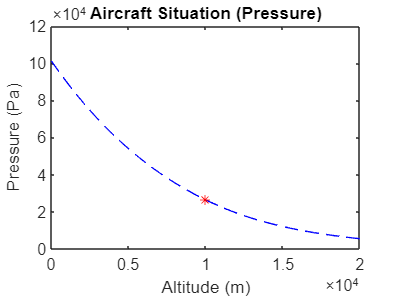

n_iter = 20000+1;
hp = linspace(0, 20000, n_iter);

    Tp = zeros(1, n_iter);
    pp = zeros(1, n_iter);
%Pressure representation
for  k = 1:11001 %Plots functions under tropopause

    Tp(k) = (To-6.5*(hp(k)/1000))-273;
    pp(k) = po*(1-0.0065*(hp(k)/To)).^5.2561;
end

for k = 11001:20001 %Plots functions above tropopause

    Tp(k) = 216.65-273;
    pp(k) = p11*exp(-g/(R*T11)*(hp(k)-h11));
end
figure(1)
plot(hp, pp, 'b--', h, p, 'r*')
    title('Aircraft Situation (Pressure)')
    xlabel('Altitude (m)')
    ylabel('Pressure (Pa)')
    xlim([0 20000])

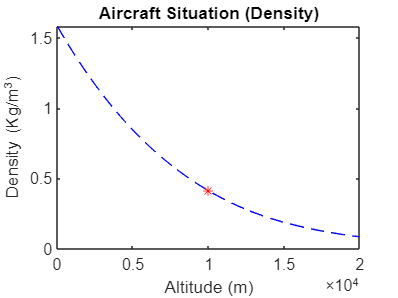

%Density representation
rhop = pp/(R*T);

figure(2)
plot(hp, rhop, 'b--', h, rho, 'r*')
    title('Aircraft Situation (Density)')
    xlabel('Altitude (m)')
    ylabel('Density (Kg/m^3)')
    xlim([0 20000])

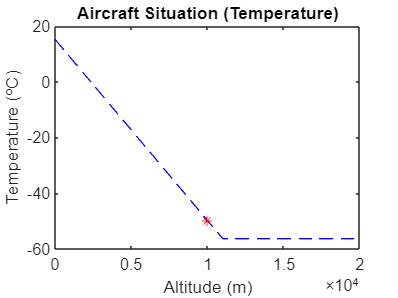

%Temperature representation
figure(3)
plot(hp, Tp, 'b--', h, T-273, 'r*')
    title('Aircraft Situation (Temperature)')
    xlabel('Altitude (m)')
    ylabel('Temperature (ºC)')
    xlim([0 20000])